# 4-6-2016 - Multisubject Anova Analysis 

%close all;clear all;clc
Z_Constants;
SUB_DIR = fullfile(myGetenv('subject_dir'));
OUTPUT_DIR = fullfile(myGetenv('OUTPUT_DIR'));

anovaBetaMags5 = [];
anovaBetaMags3 = [];
anovaBetaMags1 = [];
anovaBetaBase = [];
anovaBetaSID = {};
anovaNumStims = {};
anovaTotalMags = [];
anovaChan = {};
anovaType = {};
%answer = input('use zscore or raw values? Enter "zscore" or "raw"  \n','s');
answer = 'raw';
% exclude playback for now
%sid = SIDS{8}
for i = 6
   sid = SIDS{i}
    switch sid
        case 'd5cd55'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','d5cd55epSTATSsig'))
            stims = [54 62];
            goods = [35 36 37 44 45 46 52 53 55 60 61 63];
            
            betaChan = 53;
            typeCell = {'180'};
            typeCell = {'180'};
            
        case 'c91479'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','c91479epSTATSsig'))
            betaChan = 64;
            stims = [55 56];
            goods = [38 39 40 46 47 48 62 64];
            
            typeCell = {'180','0'};
            
        case '7dbdec'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','7dbdecepSTATSsig'))
            stims = [11 12];
            goods = [4 5 10 13 21 22 23];
            
            betaChan = 4;
            typeCell = {'180'};
        case '9ab7ab'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','9ab7abepSTATSsig'))
            betaChan = 51;
            stims = [59 60];
            goods = [42 43 50 51 52 53 57 58];
            typeCell = {'270'};
        case '702d24'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','702d24epSTATSsig'))
            betaChan = 5;
            stims = [13 14];
            %                     goods = 5;
            goods = [4 5 6 12 20 21 22];
            
            typeCell = {'270','90'};
            
        case 'ecb43e'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','ecb43eepSTATSsig'))
            dataForAnova{64} = [];
            CCEPbyNumStim{64} = [];
            ZscoredDataForAnova{64} = [];
            
            betaChan = 55;
            goods = [55 63 54 46 47 48 46];
            stims = [56 64];
            typeCell = {'270','90','Null','Random'};
            
        case '0b5a2e'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','0b5a2eepSTATSsig'))
            betaChan = 23;
            stims = [22 30];
            goods = [12 13 14 15 16 21 23 31 32 39 40];
            typeCell = {'270','90','Null'};
            
        case '0b5a2ePlayback'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','0b5a2ePlaybackepSTATSsig'))
            betaChan = 23;
            stims = [22 30];
            goods = [12 13 14 15 16 21 23 31 32 39 40];
            typeCell = {'270','90','Null'};
    end
    
    
    
    
    % here's where I pick those channels!
    chan = betaChan;
    chans = betaChan;
    
    % figure out number of test conditions
    numTypes = length(CCEPbyNumStim{51});
    
    if strcmp(sid,'0b5a2e') || strcmp(sid,'0b5a2ePlayback') || strcmp(sid,'ecb43e')
        nullType = 3;
        
    else
        nullType = NaN;
    end
    
    % cells, rather than stacked, of responses for given num stimuli
    
    for chan = chans
        % for each channel, a single stacked vector of all of the responses for a given number of stimuli
        tB = [];
        t1 = [];
        t2 = [];
        t3 = [];
        tN = [];
        
        switch(answer)
            case 'zscore'
                dataForAnova = ZscoredDataForAnova;
            case 'raw'
                
        end
        
        for i = 1:numTypes
            
            if i ~= nullType
                tempMag = dataForAnova{chan}{i}{1};
                tempLabel = dataForAnova{chan}{i}{2};
                tempKeeps = dataForAnova{chan}{i}{3};
                
                tempBase = tempMag(tempLabel(tempKeeps)==0);
                tempResp1 = tempMag(tempLabel(tempKeeps)==1);
                tempResp2 = tempMag(tempLabel(tempKeeps)==2);
                tempResp3 = tempMag(tempLabel(tempKeeps)==3);
                
                tB = [tB tempBase];
                t1 = [t1 tempResp1];
                t2 = [t2 tempResp2];
                t3 = [t3 tempResp3];
                
                
                
                %             elseif i == nullType && strcmp(sid,'ecb43e') == 0
                %                 tempMag = dataForAnova{chan}{i}{1};
                %                 tempLabel = dataForAnova{chan}{i}{2};
                %                 tempKeeps = dataForAnova{chan}{i}{3};
                %
                %                 tempBase = tempMag(tempLabel(tempKeeps)==0);
                %                 tempRespNull = tempMag(tempLabel(tempKeeps)==1);
                %
                %                 tN = [tN tempRespNull];
                
                
                
                
                lengthType = length(tempBase)+length(tempResp1)+length(tempResp2)+length(tempResp3);
                vecType = repmat(typeCell{i},lengthType,1);
                vecTypeC = cellstr(vecType)';
                anovaType = [anovaType{:} vecTypeC];
                typeResp = [tempResp3 tempResp2 tempResp1 tempBase];
                anovaTotalMags = [anovaTotalMags typeResp];
                num5S = repmat('Ct>=5',length(tempResp3),1);
                num3S= repmat('3<=Ct<=4',length(tempResp2),1);
                num1S = repmat('1<=Ct<=2',length(tempResp1),1);
                numBaseS = repmat('Base',length(tempBase),1);
                
                %             numNullS = repmat('Null',length(tN),1);
                
                b5C = cellstr(num5S)';
                b3C = cellstr(num3S)';
                b1C = cellstr(num1S)';
                BC = cellstr(numBaseS)';
                %             nC = cellstr(numNullS)';
                anovaNumStims = [anovaNumStims{:} b5C b3C b1C BC];
            end
        end
        
        % change tihs to just to lnegth(t3) to do the one way anova below
        lengthToRep = length(t3)+length(t2)+length(t1)+length(tB);
        sidString = repmat(sid,lengthToRep,1);
        %         num5S = repmat('Ct>=5',length(t3),1);
        %         num3S= repmat('3<=Ct<=4',length(t2),1);
        %         num1S = repmat('1<=Ct<=2',length(t1),1);
        %         numBaseS = repmat('Base',length(tB),1);
        %
        %         numNullS = repmat('Null',length(tN),1);
        %
        
        sidCell = cellstr(sidString)';
        %         b5C = cellstr(num5S)';
        %         b3C = cellstr(num3S)';
        %         b1C = cellstr(num1S)';
        %         BC = cellstr(numBaseS)';
        %         nC = cellstr(numNullS)';
        
        anovaBetaMags5 = [anovaBetaMags5 t3];
        anovaBetaMags3 = [anovaBetaMags3 t2];
        anovaBetaMags1 = [anovaBetaMags1 t1];
        anovaBetaBase = [anovaBetaBase tB] ;
        anovaBetaSID = [anovaBetaSID{:} sidCell];
        %         anovaNumStims = [anovaNumStims{:} b5C b3C b1C BC];
        %         anovaTotalMags = [anovaTotalMags t3 t2 t1 tB];
        %         anovaType = [anovaType typeNums];
        
        
    end
    %     [p,tbl,stats] = anova1(anovaBetaMags5,anovaBetaSID)
    %     [c,m,h,gnames] = multcompare(stats);
    
end

sid = '702d24'

p =     0.0000
    0.5386
       NaN


tbl = 6×7 cell array
    'Source'                                   'Sum Sq.'       'd.f.'    'Singular?'    'Mean Sq.'      'F'          'Prob>F'    
    'anovaNumStims(anovaType,anovaBetaSID)'    [5.6445e+04]    [   6]    [        0]    [9.4075e+03]    [13.6551]    [6.2864e-15]
    'anovaType(anovaBetaSID)'                  [  260.6768]    [   1]    [        0]    [  260.6768]    [ 0.3784]    [    0.5386]
    'anovaBetaSID'                             [         0]    [   0]    [        0]    [         0]    [      0]    [       NaN]
    'Error'                                    [6.6758e+05]    [ 969]    [        0]    [  688.9339]           []              []
    'Total'                                    [7.2425e+05]    [ 976]    [        0]              []           []              []


stats = struct with fields:
         source: 'anovan'
          resid: [977×1 double]
         coeffs: [12×1 double]
            Rtr: [8×8 double]
       rowbasis: [8×12 double]
            dfe: 969
            mse: 688.9339
    nullproject: [12×8 double]
          terms: [3×3 double]
        nlevels: [3×1 double]
     continuous: [0 0 0]
         vmeans: [3×1 double]
       termcols: [4×1 double]
     coeffnames: {12×1 cell}
           vars: [12×3 double]
       varnames: {3×1 cell}
       grpnames: {3×1 cell}
        vnested: [3×3 double]
            ems: []
          denom: []
        dfdenom: []
        msdenom: []
         varest: []
          varci: []
       txtdenom: []
         txtems: []
        rtnames: []


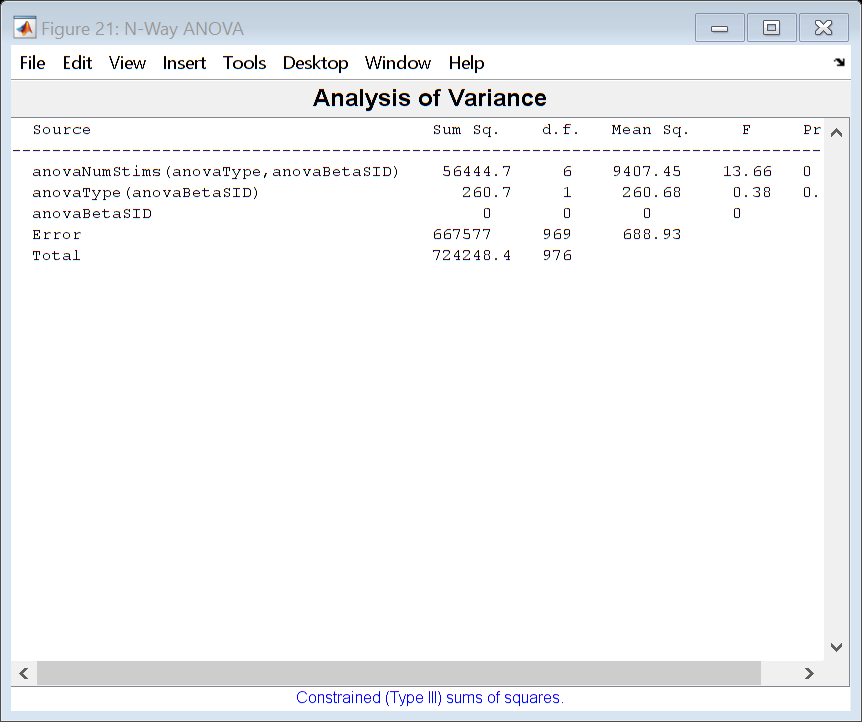

figure
[p,tbl,stats] = anovan(anovaTotalMags,{anovaNumStims,anovaType,anovaBetaSID},'varnames',{'anovaNumStims','anovaType','anovaBetaSID'},'model','interaction','nested',[0 1 1;0 0 1;0 0 0],'sstype',3)

p =     0.5807
       NaN


tbl = 5×7 cell array
    'Source'                     'Sum Sq.'       'd.f.'    'Singular?'    'Mean Sq.'    'F'         'Prob>F'
    'anovaType(anovaBetaSID)'    [  226.7613]    [   1]    [        0]    [226.7613]    [0.3054]    [0.5807]
    'anovaBetaSID'               [         0]    [   0]    [        0]    [       0]    [     0]    [   NaN]
    'Error'                      [7.2402e+05]    [ 975]    [        0]    [742.5863]          []          []
    'Total'                      [7.2425e+05]    [ 976]    [        0]            []          []          []


stats = struct with fields:
         source: 'anovan'
          resid: [977×1 double]
         coeffs: [4×1 double]
            Rtr: [2×2 double]
       rowbasis: [2×4 double]
            dfe: 975
            mse: 742.5863
    nullproject: [4×2 double]
          terms: [2×2 double]
        nlevels: [2×1 double]
     continuous: [0 0]
         vmeans: [2×1 double]
       termcols: [3×1 double]
     coeffnames: {4×1 cell}
           vars: [4×2 double]
       varnames: {2×1 cell}
       grpnames: {2×1 cell}
        vnested: [2×2 double]
            ems: []
          denom: []
        dfdenom: []
        msdenom: []
         varest: []
          varci: []
       txtdenom: []
         txtems: []
        rtnames: []


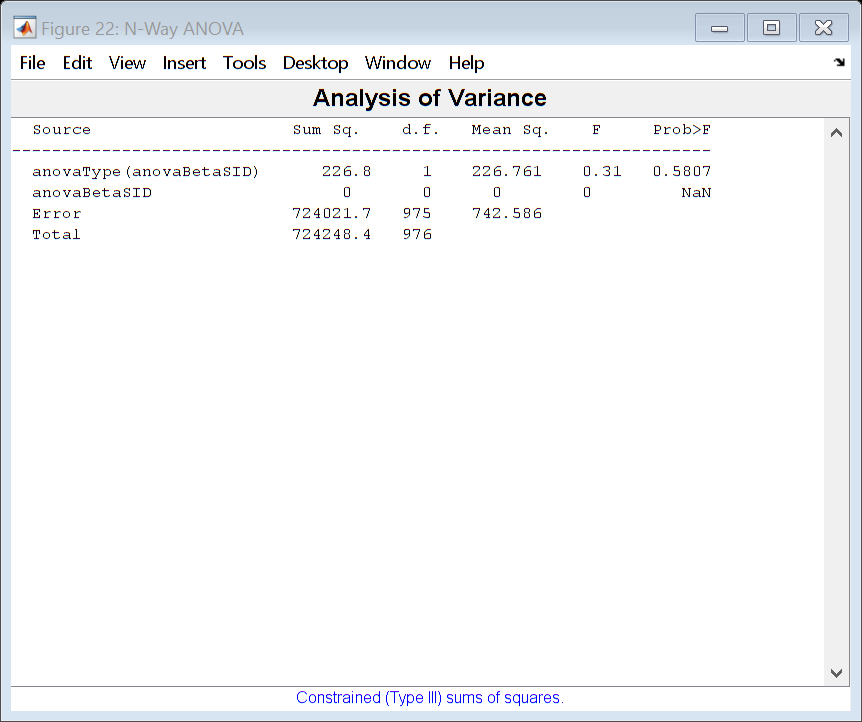

[p,tbl,stats] = anovan(anovaTotalMags,{anovaType,anovaBetaSID},'varnames',{'anovaType','anovaBetaSID'},'model','interaction','nested',[0 1; 0 0])

p =     0.0000
    0.5386
       NaN
    0.0015
       NaN
       NaN
       NaN


tbl = 10×7 cell array
    'Source'                                  'Sum Sq.'       'd.f.'    'Singular?'    'Mean Sq.'      'F'          'Prob>F'    
    'anovaNumStims'                           [3.9862e+04]    [   3]    [        0]    [1.3287e+04]    [19.2870]    [3.7552e-12]
    'anovaType'                               [  260.6768]    [   1]    [        0]    [  260.6768]    [ 0.3784]    [    0.5386]
    'anovaBetaSID'                            [         0]    [   0]    [        0]    [         0]    [      0]    [       NaN]
    'anovaNumStims*anovaType'                 [1.0646e+04]    [   3]    [        0]    [3.5488e+03]    [ 5.1511]    [    0.0015]
    'anovaNumStims*anovaBetaSID'              [         0]    [   0]    [        0]    [         0]    [      0]    [       NaN]
    'anovaType*anovaBetaSID'                  [         0]    [   0]    [        0]    [         0]    [      0]    [       NaN]
    'anovaNumStims*anovaType*anovaBetaSID'    [         0]    [   0]    [  

stats = struct with fields:
         source: 'anovan'
          resid: [977×1 double]
         coeffs: [30×1 double]
            Rtr: [8×8 double]
       rowbasis: [8×30 double]
            dfe: 969
            mse: 688.9339
    nullproject: [30×8 double]
          terms: [7×3 double]
        nlevels: [3×1 double]
     continuous: [0 0 0]
         vmeans: [3×1 double]
       termcols: [8×1 double]
     coeffnames: {30×1 cell}
           vars: [30×3 double]
       varnames: {3×1 cell}
       grpnames: {3×1 cell}
        vnested: []
            ems: []
          denom: []
        dfdenom: []
        msdenom: []
         varest: []
          varci: []
       txtdenom: []
         txtems: []
        rtnames: []


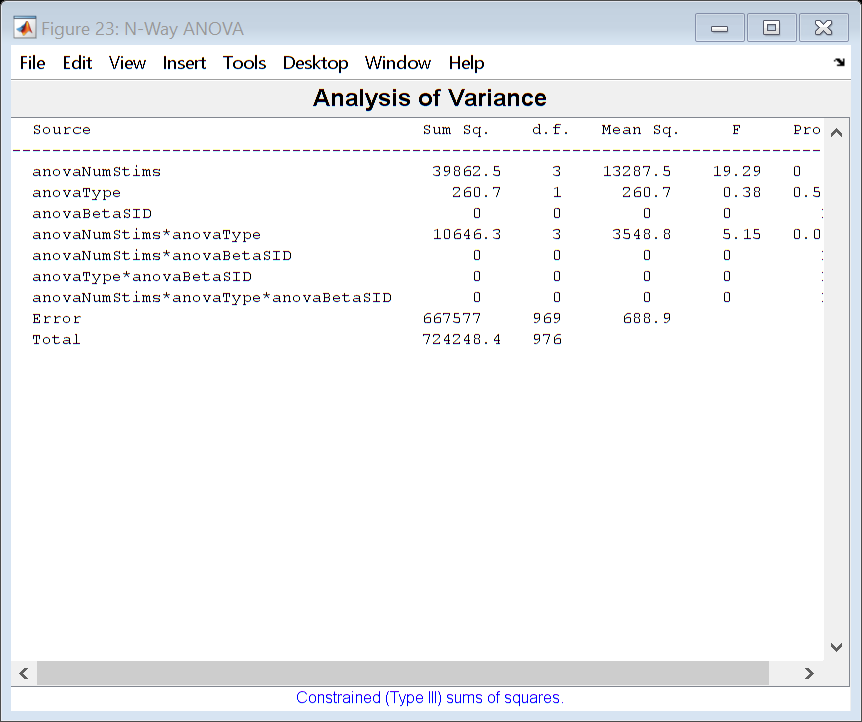

[p,tbl,stats] = anovan(anovaTotalMags,{anovaNumStims,anovaType,anovaBetaSID},'model','full','varnames',{'anovaNumStims','anovaType','anovaBetaSID'})

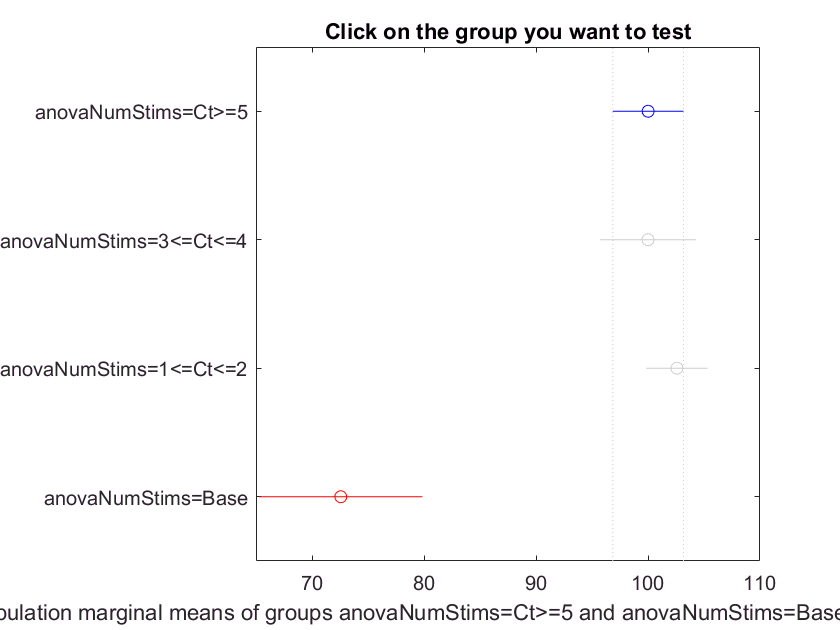

c =     1.0000    2.0000   -7.5682    0.0139    7.5959    1.0000
    1.0000    3.0000   -8.2345   -2.5737    3.0872    0.6471
    1.0000    4.0000   16.9224   27.4419   37.9613    0.0000
    2.0000    3.0000   -9.6651   -2.5875    4.4901    0.7837
    2.0000    4.0000   16.0831   27.4280   38.7728    0.0000
    3.0000    4.0000   19.8537   30.0155   40.1774    0.0000


m =   100.0108    1.7286
   99.9970    2.3921
  102.5845    1.3666
   72.5690    3.7120


h =   Figure (24: Multiple comparison of population marginal means) with properties:

      Number: 24
        Name: 'Multiple comparison of population marginal means'
       Color: [0.9400 0.9400 0.9400]
    Position: [1000 918 560 420]
       Units: 'pixels'

  Show all properties


gnames = 4×1 cell array
    'anovaNumStims=Ct>=5'
    'anovaNumStims=3<=Ct<=4'
    'anovaNumStims=1<=Ct<=2'
    'anovaNumStims=Base'



%[p,tbl,stats] = anovan(anovaTotalMags,{anovaNumStims,anovaType},'varnames',{'anovaNumStims','anovaType'},'model','full

figure
[c,m,h,gnames] = multcompare(stats)

[gnames num2cell(m)]

ans = 4×3 cell array
    'anovaNumStims=Ct>=5'       [100.0108]    [1.7286]
    'anovaNumStims=3<=Ct<=4'    [ 99.9970]    [2.3921]
    'anovaNumStims=1<=Ct<=2'    [102.5845]    [1.3666]
    'anovaNumStims=Base'        [ 72.5690]    [3.7120]


figure
% bar(m(:,1))
% hold on
errorbar((1:length(m(:,1))),flip(m(:,1)),flip(m(:,2)),'ro','linestyle','none','linew',2','color','r')
% xlabel('Patients and Task','fontsize',16,'fontweight','bold')
ylabel('Zscored CCEP Magnitude','fontsize',14,'fontweight','bold')
xlabel('Number of Conditioning Pulses','fontsize',14,'fontweight','bold')

ax = gca;
ax.XTickLabelMode = 'manual'

ax =   Axes with properties:

             XLim: [1 4]
             YLim: [65 105]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1148 0.7750 0.8102]
            Units: 'normalized'

  Show all properties


ax.XTick = [1 2 3 4]

ax =   Axes with properties:

             XLim: [1 4]
             YLim: [65 105]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1148 0.7750 0.8102]
            Units: 'normalized'

  Show all properties


ax.XTickLabel = {'Baseline','1->2','3->4','>5' }

ax =   Axes with properties:

             XLim: [1 4]
             YLim: [65 105]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1148 0.7750 0.8102]
            Units: 'normalized'

  Show all properties


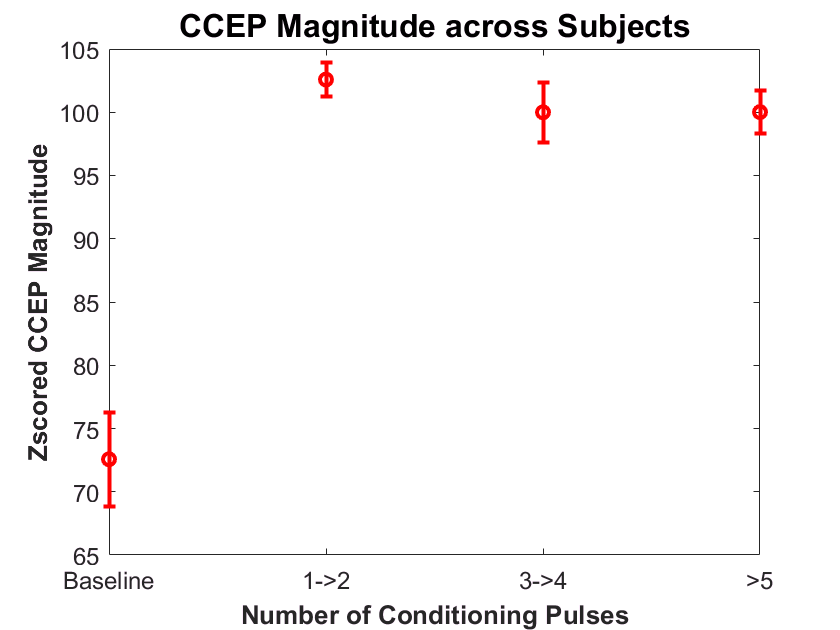

ax.FontSize = 12;
% ax.FontWeight = 'bold';
% set(gca,'XtickLabel',{'','>5','3->4', '1->2','Baseline'},'fontsize',14,'fontweight','bold')
title({'CCEP Magnitude across Subjects';},'fontsize',16,'fontweight','bold')

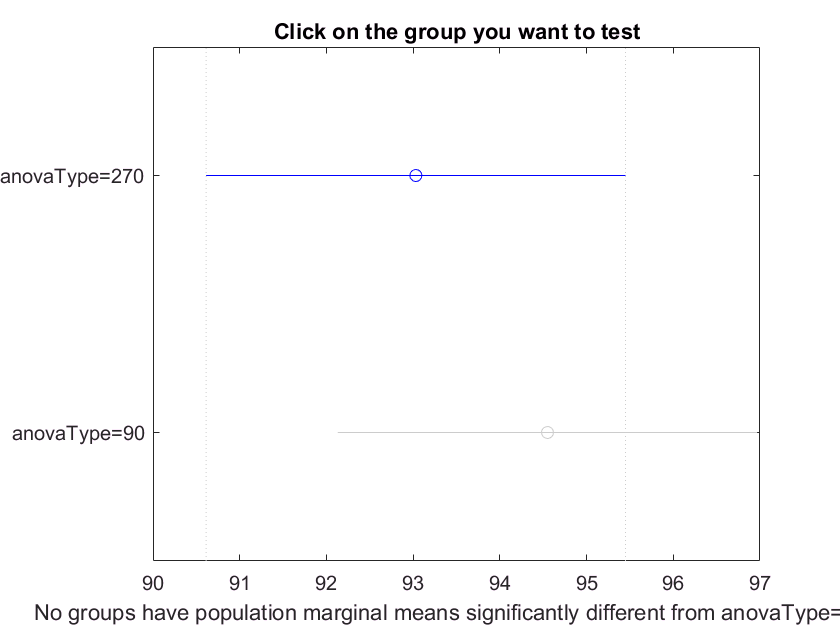

cM =     1.0000    2.0000   -6.3543   -1.5179    3.3185    0.5385


mM =    93.0314    1.8000
   94.5493    1.6879


hM =   Figure (26: Multiple comparison of population marginal means) with properties:

      Number: 26
        Name: 'Multiple comparison of population marginal means'
       Color: [0.9400 0.9400 0.9400]
    Position: [1000 918 560 420]
       Units: 'pixels'

  Show all properties


gnamesM = 2×1 cell array
    'anovaType=270'
    'anovaType=90'



figure
[cM,mM,hM,gnamesM] = multcompare(stats,'Dimension',[2])

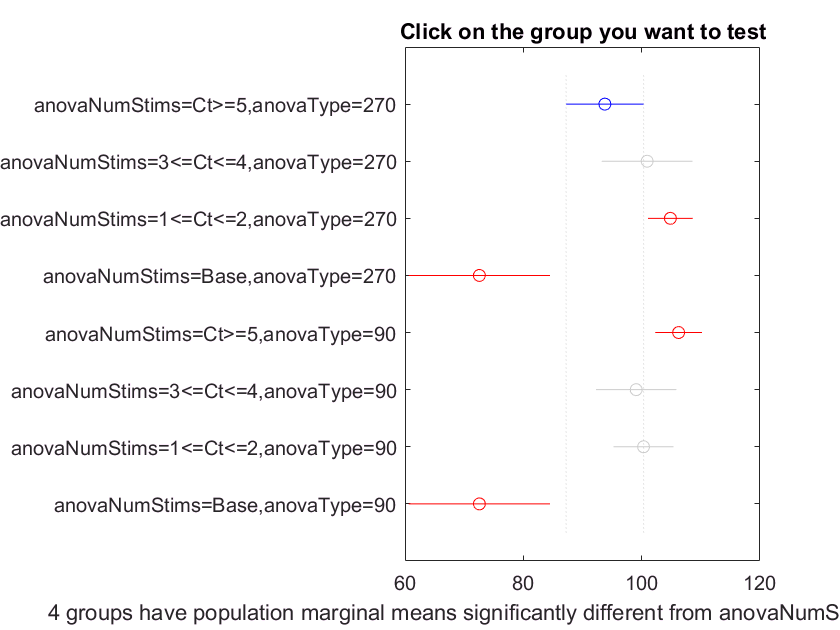

cM =     1.0000    2.0000  -21.4264   -7.1473    7.1318    0.7985
    1.0000    3.0000  -21.3629  -11.0735   -0.7841    0.0245
    1.0000    4.0000    2.7748   21.2096   39.6444    0.0115
    1.0000    5.0000  -22.9427  -12.4645   -1.9863    0.0075
    1.0000    6.0000  -18.6971   -5.2895    8.1181    0.9334
    1.0000    7.0000  -18.2061   -6.5383    5.1295    0.6884
    1.0000    8.0000    2.7748   21.2096   39.6444    0.0115
    2.0000    3.0000  -15.6042   -3.9262    7.7518    0.9717
    2.0000    4.0000    9.1125   28.3569   47.6013    0.0002
    2.0000    5.0000  -17.1619   -5.3172    6.5274    0.8750


mM =    93.7786    3.0720
  100.9259    3.5718
  104.8521    1.4449
   72.5690    5.2495
  106.2431    1.5857
   99.0681    3.1830
  100.3169    2.3200
   72.5690    5.2495


hM =   Figure (27: Multiple comparison of population marginal means) with properties:

      Number: 27
        Name: 'Multiple comparison of population marginal means'
       Color: [0.9400 0.9400 0.9400]
    Position: [1000 918 560 420]
       Units: 'pixels'

  Show all properties


gnamesM = 8×1 cell array
    'anovaNumStims=Ct>=5,anovaType=270'
    'anovaNumStims=3<=Ct<=4,anovaType=270'
    'anovaNumStims=1<=Ct<=2,anovaType=270'
    'anovaNumStims=Base,anovaType=270'
    'anovaNumStims=Ct>=5,anovaType=90'
    'anovaNumStims=3<=Ct<=4,anovaType=90'
    'anovaNumStims=1<=Ct<=2,anovaType=90'
    'anovaNumStims=Base,anovaType=90'



% figure
% results = multcompare(stats,'Dimension',[3])

figure
[cM,mM,hM,gnamesM] = multcompare(stats,'Dimension',[1 2])

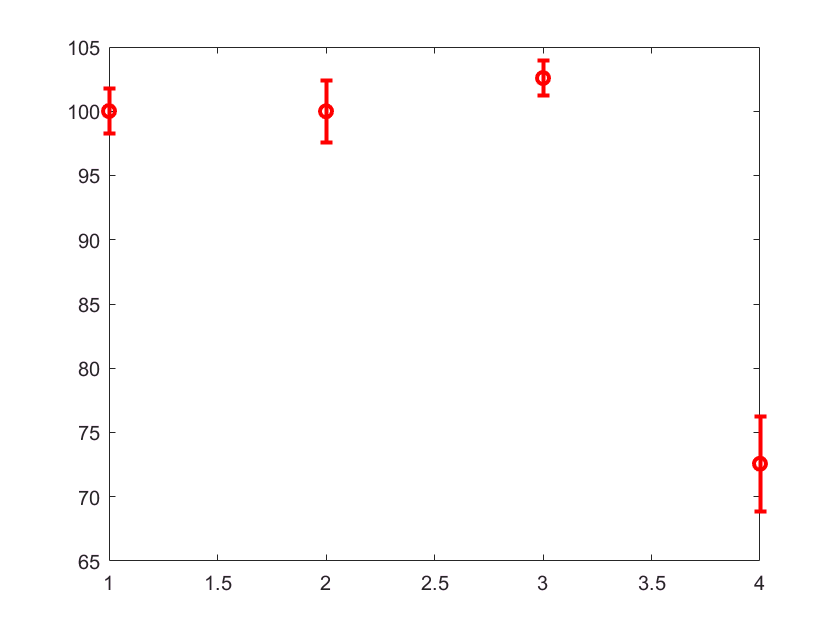



errorbar((1:length(m(:,1))),m(:,1),m(:,2),'ro','linestyle','none','linew',2','color','r')


figure
[cM,mM,hM,gnamesM] = multcompare(stats,'Dimension',[2 3])

Error using multcompare (line 245)
DIM must specify only categorical factors with 2 or more degrees of freedom.



figure
[cM,mM,hM,gnamesM] = multcompare(stats,'Dimension',[1 3])

[p,tbl,stats] = anova1(anovaTotalMags,anovaNumStims)
multcompare(stats)